% Plant
L = 0.0375;
R = 0.048;
Gp = tf([1], [L, R]);

% PI Controller
Kp = 1500;
Ki = 350000;
C = tf([Kp, Ki], [1, 0]);

% Open loop
OL = C * Gp;

% Closed loop (unity feedback)
CL = feedback(OL, 1);

% Step response info
info = stepinfo(CL, 'SettlingTimeThreshold', 0.02)

info = struct with fields:
         RiseTime: 5.3990e-05
    TransientTime: 9.2147e-05
     SettlingTime: 9.2147e-05
      SettlingMin: 0.9005
      SettlingMax: 1.0050
        Overshoot: 0.4990
       Undershoot: 0
             Peak: 1.0050
         PeakTime: 1.8413e-04


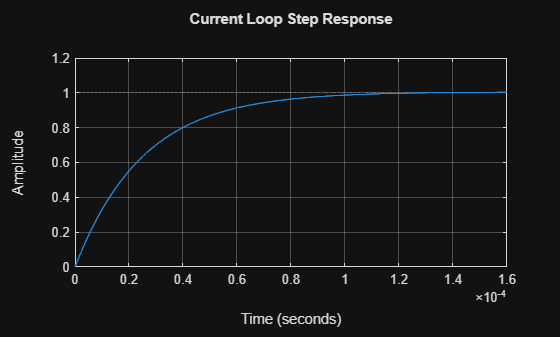


% Plot step response
figure
step(CL)
title('Current Loop Step Response')
grid on

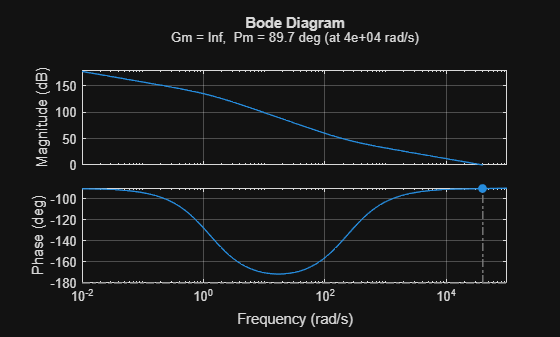


% Bode plot for phase/gain margin
figure
margin(OL)
grid on


% Check poles
poles = pole(CL)

% Frequency response at 50Hz
w_50Hz = 2*pi*50;
[mag, phase] = bode(CL, w_50Hz);
fprintf('Gain at 50Hz: %.4f\n', mag)
fprintf('Phase at 50Hz: %.2f degrees\n', phase)
fprintf('Settling time: %.4f seconds\n', info.SettlingTime)
fprintf('Overshoot: %.2f%%\n', info.Overshoot)